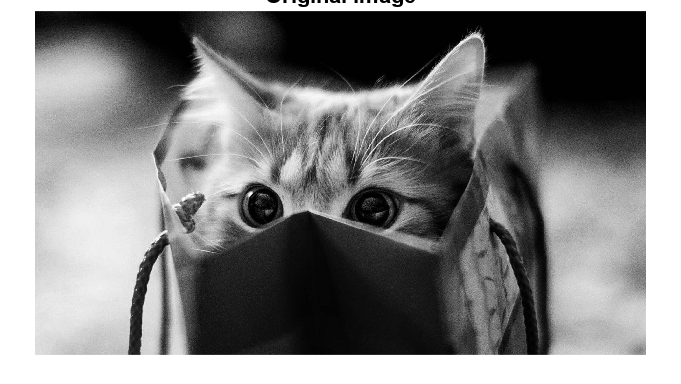

clear
clf

% Read original image and convert to grayscale
rgb_image = imread("cat.jpg");
gray_image = im2gray(rgb_image);
A = im2double(gray_image);

% Show the original image
imshow(A)
title(['Original image']);

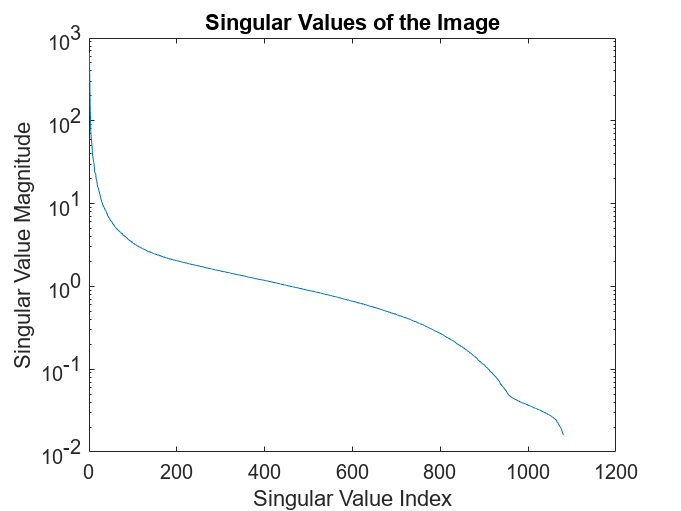


% Compute the singular values of A
[U, S, V] = svd(A);
figure;
semilogy(diag(S));
title('Singular Values of the Image');
xlabel('Singular Value Index');
ylabel('Singular Value Magnitude');

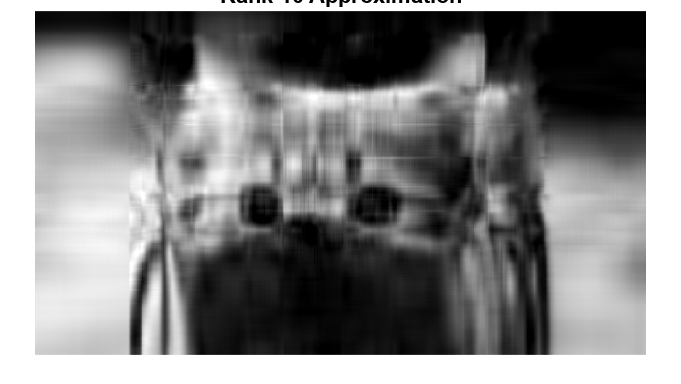

The singular value sigma_10 is: 33.429


The compression ratio for rank-10 approximation is: 0.014472


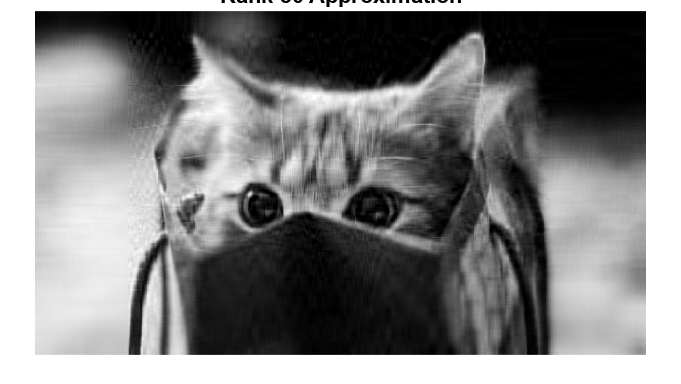

The singular value sigma_30 is: 10.3451


The compression ratio for rank-30 approximation is: 0.043417


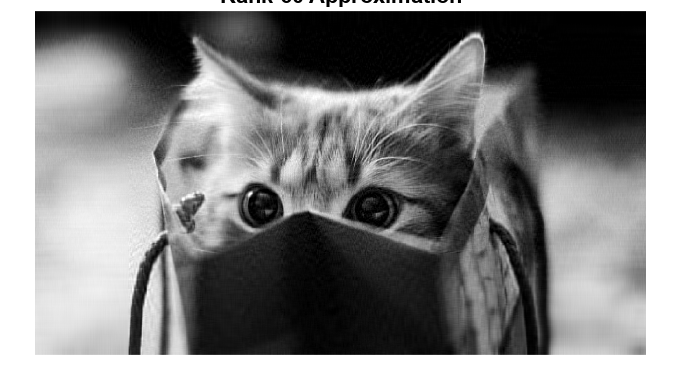

The singular value sigma_60 is: 5.2111


The compression ratio for rank-60 approximation is: 0.086834


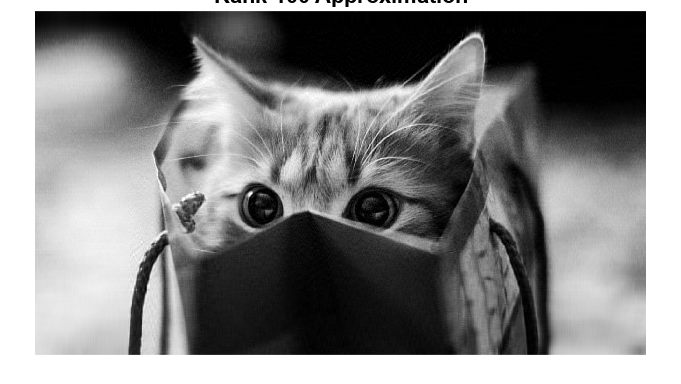

The singular value sigma_100 is: 3.3709


The compression ratio for rank-100 approximation is: 0.14472



% k values to show
k_values = [10, 30, 60, 100];

% Create rank approximation Ak
for i = 1:length(k_values)
    k = k_values(i);

    % Create the rank-k approximation Ak
    Ak = U(:, 1:k) * S(1:k, 1:k) * V(:, 1:k)';

    % Visualize the rank-k approximation
    figure;
    imshow(Ak);
    title(['Rank-', num2str(k), ' Approximation']);

    % Show the singular value for k
    sigma_k = S(k, k);
    disp(['The singular value sigma_', num2str(k), ' is: ', num2str(sigma_k)]);

    % Show the compression ratio for k
    compression_ratio = (size(U,1)*k + size(V,1)*k + k) / numel(A);
    disp(['The compression ratio for rank-', num2str(k), ' approximation is: ', num2str(compression_ratio)]);

end